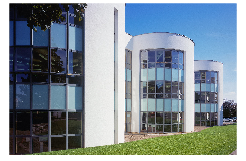

clc;
clear;
cd /Users/lumizhang/Documents/GitHub/AI_B_Project_2023

target = imread("dataset/mosaic_target2.jpg");
imshow(target)

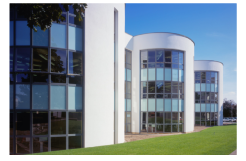

target = imgaussfilt(target,4);
imshow(target);

We first calculate the average rgb histogram for all of the 500 images.

tiles = {};

% Read the Natural images to tiles
names = cell2mat(splitlines(fileread("dataset/natural_training.txt")));
names = strcat("dataset/", names);
fit_num = numel(names);
for i = 1:numel(names)
    name = names(i, :);
    source = rgb2hsv(imread(name));
    h = mean(source(:,:,1),'all');
    s = mean(source(:,:,2),'all');
    v = mean(source(:,:,3),'all');
    tiles{i,1} = name;
    tiles{i,2} = h;
    tiles{i,3} = s;
    tiles{i,4} = v;
end

% Read the Manmade images to tiles
names = cell2mat(splitlines(fileread("dataset/manmade_training.txt")));
names = strcat("dataset/", names);
for i = 1:numel(names)
    name = names(i, :);
    source = rgb2hsv(imread(name));
    h = mean(source(:,:,1),'all');
    s = mean(source(:,:,2),'all');
    v = mean(source(:,:,3),'all');
    tiles{i + fit_num,1} = name;
    tiles{i + fit_num,2} = h;
    tiles{i + fit_num,3} = s;
    tiles{i + fit_num,4} = v;
end

num_x_tiles = 50;
num_y_tiles = 50;
target_size = size(target);
x_width = floor(target_size(2) / num_x_tiles) + 1;
y_width = floor(target_size(1) / num_y_tiles) + 1;

Testing the resizing of the image

%target_resized = imresize(target, [y_width x_width]);
%imshow(target_resized)

And it worked well

source_cell = {};
target_hsv = rgb2hsv(target);
alpha = 0.4;
beta = 0.3;
for i = 1:num_x_tiles
    for j = 1:num_y_tiles
        x_start = (i - 1) * x_width + 1;
        x_end = i * x_width;
        y_start = (j - 1) * y_width + 1;
        y_end = j * y_width;
        if x_end > target_size(2)
            x_end = target_size(2);
        end
        if y_end > target_size(1)
            y_end = target_size(1);
        end
        mat = target_hsv(y_start:y_end, x_start:x_end, :);
        mat_h = mean(mat(:,:,1), 'all');
        mat_s = mean(mat(:,:,2), 'all');
        mat_v = mean(mat(:,:,3), 'all');

        fit = inf;
        for k = 1:1000
            h_dif = abs(mat_h - tiles{k, 2});
            s_dif = abs(mat_s - tiles{k, 3});
            v_dif = abs(mat_v - tiles{k, 4});

            score = alpha * h_dif + beta * s_dif + (1 - alpha - beta) * v_dif;
            if score < fit
                fit = score;
                source_cell{j,i} = tiles{k, 1};
            end
        end
    end
end

mosaic_size = size(source_cell);
images = {};

for i = 1:mosaic_size(2)
    for j = 1:mosaic_size(1)
        images{j, i} = imresize(imread(source_cell{j,i}), [y_width x_width]);
    end
end

rowImage = cell(mosaic_size(1),1);
for i = 1:mosaic_size(1)
    rowImage{i} = horzcat(images{i,:});
end

mosaic = vertcat(rowImage{:});

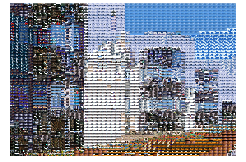

imshow(mosaic)

%imwrite(mosaic, "mosaic1_output.jpg","jpg")

I noticed the picture on the part where it is green is not very right.

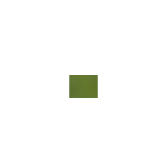

target_part = target_hsv((1600-20) : 1600, (86*25) : (87 * 25), :);
imshow(hsv2rgb(target_part));

part_h = mean(target_part(:,:,1),'all');
part_s = mean(target_part(:,:,2),'all');
part_v = mean(target_part(:,:,3),'all');

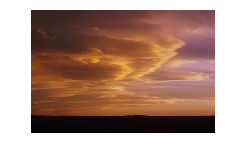

weird_pic = rgb2hsv(imread("dataset/natural_training/sun_abzxdwfaynnlysye.jpg"));
imshow(hsv2rgb(weird_pic))

weird_h = mean(weird_pic(:,:,1), 'all');
weird_s = mean(weird_pic(:,:,2), 'all');
weird_v = mean(weird_pic(:,:,3), 'all');

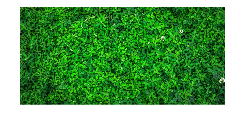

green_pic = rgb2hsv(imread("dataset/natural_training/sun_coijsoiejboasolf.jpg"));
imshow(hsv2rgb(green_pic));

green_h = mean(green_pic(:,:,1), 'all');
green_s = mean(green_pic(:,:,2), 'all');
green_v = mean(green_pic(:,:,3), 'all');